## **Question 1:**

We define the standard **LTI system** used in the problem first.

We then use the **desired closed loop poles **to calculate the control gain **K **which has been used to stabilize the closed loop system. The purpose of the first question was to test the system for various values of **sampling time** **h **for which the system remains stable.

%% Question 1:
clc

% Desired poles (complex conjugate):
s1 = -2 + 1j;
s2 = -2 - 1j;  

desiredPoles = [s1, s2]; 

% student id = 6492053

a = 6;
b = 9;
c = 3;

A = [0, 0.5+c; 0.5 + abs(a-b), 1];
B = [1 0]';

% Assuming full state feedback, assuming 0 transmission:

C = [1 1];

% Calculate the gain for the desired poles
K = place(A, B, desiredPoles);

% Open loop eigenvalue:
disp(eig(A));

   -3.0355
    4.0355



% Define the sampling intervals h:

h_values = [1e-6:0.01:0.1 0.1:0.05:0.623]; % calculated from h << 2pi/|w| where |w| = 1 (from the desired closed loop poles).

% Initialize the spectral radius computation
sr = zeros(length(h_values), 1);

% Loop through each sampling interval to compute spectral radius:

for i = 1:length(h_values)
    h = h_values(i);
    sr_i = computeSpectralRadius(A,B,C,K,h);
    % Store into array 
    sr(i) = sr_i;
end

figure

plot(h_values,sr,'-','LineWidth',2.0)
xlabel('Sampling interval (h)')
ylabel('Spectral radius \rho')
title('Spectral radius vs. Sampling Time')
% A black line shows the point of rho (spectral radius) = 1 beyond which
% the system becomes unstable.
hold on
yline(1, 'k-', 'LineWidth', 1.5);
xline(0.623,'--or','LineWidth',1.5);

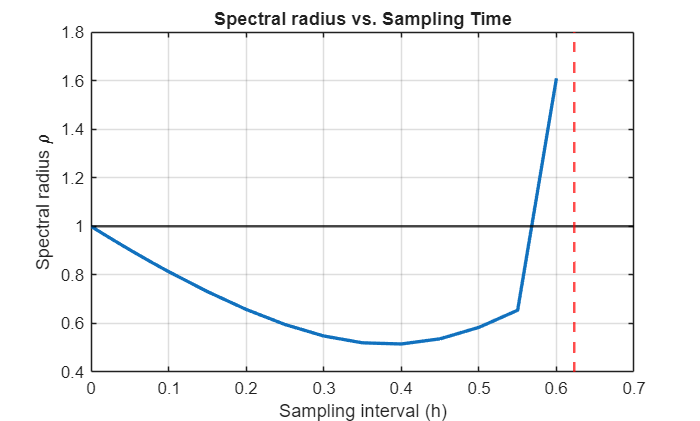

hold off
grid on;

% function for computing the spectral radius for system with no delay:

function sr = computeSpectralRadius(A,B,C,K,h)
    % Define the state-space system
    sys = ss(A, B, C, 0);
    sysd = c2d(sys, h, 'zoh'); % Discretize the continuous system

    [F,G,~,~] = ssdata(sysd);

    sr = max(abs(eig(F-G*K)));
end

We  can observe in this plot that with increasing sampling time h, we first observe an increase in stability of the system (the different modes decay faster) and then after h = 0.4 it starts becoming unstable again and then between h = 0.5 and 0.6, the spectral radius crosses 1 implying the system becomes unstable after that, and with further increase in h, the system modes blow up.

## Question 2:

**2.1 **Next we consider the case when **delays** are present in the **networked system**. Assume that the system is affected by a **constant delay τ ∈ [0,2h)**, and it is controlled with the **static controller K**. Assume a mechanism in which the controller holds the last input computed but reset the input to zero if at an update time sk the applied input is older than 2 samples. That is, in the time interval **[sk, sk+1]** the controller is never applying an input **ur** where **r ≤ k − 2**

Study by testing on sufficiently many combinations **(h,τ)** of sampling intervals and system delays that result in an **asymptotically stable closed-loop**. Provide plots illustrating the **combinations of (h,τ) **retaining stabilit

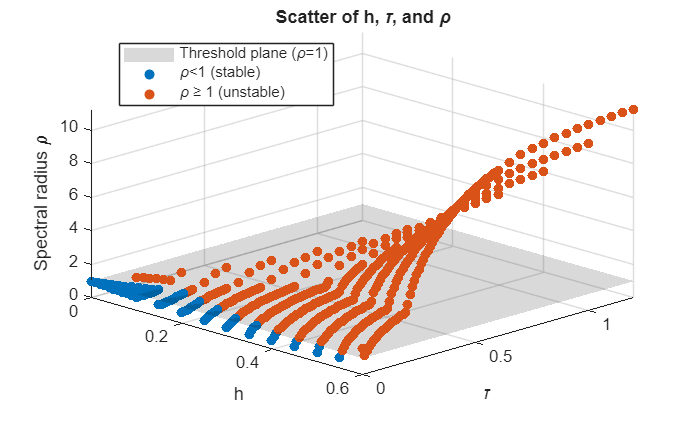

% For each h store tau vectors using cell. 
tau_cells = cell(length(h_values),1);

% Create an array to store spectral radius spectral radius vector for each h:
sr_cells = cell(length(h_values),1);

for i = 1:length(h_values)
    
    h = h_values(i);

    % Tau vector corresponding to this h:

    tau_values = [0:0.01:h h:0.05:2*h];

    % Store tau vector:

    tau_cells{i} = tau_values;

    sr_values = NaN(size(tau_values));

    for j = 1:length(tau_values)

        % Get the current tau value

        tau = tau_values(j); 

        f = @(s) expm(A*s) * B; 

        % Define the discrete time system:

        Fx = expm(A*h);

        if tau < h
            Fu = integral(@(s) f(s), h-tau, h, 'ArrayValued',true);
            G1 = integral(@(s) f(s), 0, h-tau, 'ArrayValued',true);
        elseif tau >=h && tau <2*h
            Fu = integral(@(s) f(s), 0, 2*h-tau, 'ArrayValued',true);
            G1 = [0 0]';
        elseif tau == 0
            G1 = integral(@(s) f(s), 0, 2*h-tau, 'ArrayValued',true)
            Fu = [0 0]';
        else
            Fu = [0 0]';
            G1 = [0 0]';
        end

        F = [Fx, Fu; zeros(1,size(Fx,1)), 0];
        G = [G1; eye(1)];

        Kn = [K, 0];
        sr_values(j) = max(abs(eig(F - G*Kn)));
    end
    sr_cells{i} = sr_values;
end

% Find longest tau vector
max_len = max(cellfun(@length, tau_cells));

% Build matrices for scatter3: rows correspond to h index, columns to tau samples
H_matrix = NaN(length(h_values), max_len);
Tau_matrix = NaN(length(h_values), max_len);
SR_matrix = NaN(length(h_values), max_len);

for i = 1:length(h_values)
    nx = length(tau_cells{i});
    H_matrix(i,1:nx) = h_values(i);               % same h for all tau samples at row i
    Tau_matrix(i,1:nx) = tau_cells{i};            % tau samples
    SR_matrix(i,1:nx) = sr_cells{i};              % corresponding spectral radii
end

% Flatten matrices to vectors for scatter3, removing NaNs
H_vec = H_matrix(~isnan(H_matrix));
Tau_vec = Tau_matrix(~isnan(Tau_matrix));
SR_vec = SR_matrix(~isnan(SR_matrix));

% Plot the threshold plane (spectral radius, rho = 1) spanning the h and tau ranges
h_min = min(H_vec); h_max = max(H_vec);
tau_min = min(Tau_vec); tau_max = max(Tau_vec);
[H_plane, Tau_plane] = meshgrid(linspace(h_min,h_max,2), linspace(tau_min,tau_max,2));
Rho_plane = ones(size(H_plane)); % plane at rho = 1

surf(H_plane, Tau_plane, Rho_plane, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'FaceColor', [0 0 0]);
hold on;

% Re-plot points in two colors: blue for rho < 1, red for rho >= 1
idx_below = SR_vec < 1;
idx_above = SR_vec >= 1;

scatter3(H_vec(idx_below), Tau_vec(idx_below), SR_vec(idx_below), 36, repmat([0 0.4470 0.7410], sum(idx_below),1), 'filled'); % blue
scatter3(H_vec(idx_above), Tau_vec(idx_above), SR_vec(idx_above), 36, repmat([0.8500 0.3250 0.0980], sum(idx_above),1), 'filled'); % red

xlabel('h');
ylabel('\tau');
zlabel('Spectral radius \rho');
title('Scatter of h, \tau, and \rho');
grid on;

% Add legend
legend('Threshold plane (\rho=1)','\rho<1 (stable)',  '\rho\geq1 (unstable)', 'Location', 'best')

hold off
view(45,30)

We can clearly observe in the plot, on the one hand increasing h leads to an increase in instability, and on the other hand for the same value of h, increasing tau increases instability.

**2.3: **Select a sampling interval h that guarantees stability under no delays. Redesign the controller to improve the robustness against delays, that is, try to design a controller that increases the range of tolerable delays for the selected h. Think about designing now a dynamic controller instead.

% In accordance with the plot made in Question 2.1 we select h = 0.2 as the
% sampling interval which guarantees stability for no delays. Now we must
% see if the range of tolerable delays can be increased for h = 0.2

h = 0.2;

tau_values = 0.05:0.01:0.25;
sr_values = zeros(1,length(tau_values));

for i = 1:length(tau_values)
    % Get the current tau value
    tau = tau_values(i);
    f = @(s) expm(A*s)*B;

    % Define the discrete time system:

    Fx = expm(A*h);

    if tau < h
        Fu = integral(@(s) f(s), h-tau, h, 'ArrayValued',true);
        G1 = integral(@(s) f(s), 0, h-tau, 'ArrayValued',true);
    elseif tau >=h && tau <2*h
        Fu = integral(@(s) f(s), 0, 2*h-tau, 'ArrayValued',true);
        G1 = [0 0]';
    else
        Fu = [0 0]';
        G1 = [0 0]';
    end

    F = [Fx Fu; zeros(1,size(Fx,1)), 0];
    G = [G1; 0];


    X = sdpvar(3,3);
    Y = sdpvar(1,3);
    alpha = 0.9;
    sigma = sdpvar(1);

    Schur = [alpha^2*X X*F'-Y'*G'; F*X-G*Y X];
    Gain_LMI = [sigma*eye(1) Y; Y' X];

    cons = [X>=1e-6*eye(3), sigma>=1e-6, Schur>=1e-6*eye(size(Schur)), Gain_LMI>=0];

    obj = sigma;

    result = optimize(cons,obj);
    K = value(Y)/value(X);

    disp(result.info);
    value(K);

    K

    sr_values(i) = max(abs(eig(F - G * K)))
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.88E-01 1.20E+00 0.000 0.2670 0.9000 0.9000   1.67  1  1  2.4E+00
  2 :  -1.26E-03 5.68E-02 0.000 0.0473 0.9900 0.9900   1.65  1  1  5.6E-01
  3 :  -2.38E-04 1.06E-02 0.000 0.1862 0.9000 0.9000   1.01  1  1  1.3E-01
  4 :  -4.69E-05 1.99E-03 0.000 0.1879 0.9000 0.9000   1.00  1  1  2.3E-02
  5 :  -1.06E-05 3.79E-04 0.000 0.1904 0.9000 0.9000   0.99  1  1  3.8E-03
  6 :  -3.83E-06 7.71E-05 0.000 0.2037 0.9000 0.9000   0.95  1  1  8.6E-05
  7 :  -3.17E-06 1.93E-05 0.000 0.2503 0.9000 0.9000   0.74  1  1  2.6E-05
  8 :  -7.39E-06 4.83E-06 0.000 0.2503 0.9000 0.9000   0.06  1  2  1.6E-05
  9 :  -2.52E-05 1.26E-06 0.000 0.2602 0.9000 0.9000  -0.66  1  2  1.4E-05
 10 :  -6.81E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    10.4237   12.0186    0.4720


sr_values =     0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.87E-01 1.20E+00 0.000 0.2674 0.9000 0.9000   1.67  1  1  2.4E+00
  2 :  -1.34E-03 5.75E-02 0.000 0.0478 0.9900 0.9900   1.64  1  1  5.6E-01
  3 :  -2.56E-04 1.08E-02 0.000 0.1879 0.9000 0.9000   1.02  1  1  1.4E-01
  4 :  -5.08E-05 2.05E-03 0.000 0.1896 0.9000 0.9000   1.00  1  1  2.6E-02
  5 :  -1.15E-05 3.93E-04 0.000 0.1920 0.9000 0.9000   0.99  1  1  4.3E-03
  6 :  -4.05E-06 8.06E-05 0.000 0.2049 0.9000 0.9000   0.95  1  1  9.0E-05
  7 :  -3.23E-06 2.02E-05 0.000 0.2510 0.9000 0.9000   0.75  1  2  2.7E-05
  8 :  -7.19E-06 5.21E-06 0.000 0.2573 0.9000 0.9000   0.09  1  2  1.6E-05
  9 :  -2.53E-05 1.33E-06 0.000 0.2546 0.9000 0.9000  -0.65  1  2  1.5E-05
 10 :  -7.01E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    11.4227   13.1705    0.6087


sr_values =     0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.87E-01 1.21E+00 0.000 0.2678 0.9000 0.9000   1.67  1  1  2.4E+00
  2 :  -1.42E-03 5.81E-02 0.000 0.0482 0.9900 0.9900   1.64  1  1  5.6E-01
  3 :  -2.72E-04 1.10E-02 0.000 0.1893 0.9000 0.9000   1.02  1  1  1.5E-01
  4 :  -5.43E-05 2.10E-03 0.000 0.1911 0.9000 0.9000   1.00  1  1  2.7E-02
  5 :  -1.22E-05 4.07E-04 0.000 0.1934 0.9000 0.9000   0.99  1  1  4.7E-03
  6 :  -4.24E-06 8.38E-05 0.000 0.2060 0.9000 0.9000   0.95  1  1  1.9E-04
  7 :  -3.28E-06 2.11E-05 0.000 0.2516 0.9000 0.9000   0.76  1  1  2.8E-05
  8 :  -7.02E-06 5.55E-06 0.000 0.2632 0.9000 0.9000   0.12  1  2  1.7E-05
  9 :  -2.60E-05 1.35E-06 0.000 0.2439 0.9000 0.9000  -0.64  1  4  1.5E-05
 10 :  -7.62E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    12.5629   14.4852    0.7661


sr_values =     0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.87E-01 1.21E+00 0.000 0.2682 0.9000 0.9000   1.67  1  1  2.4E+00
  2 :  -1.48E-03 5.86E-02 0.000 0.0486 0.9900 0.9900   1.64  1  1  5.6E-01
  3 :  -2.87E-04 1.12E-02 0.000 0.1906 0.9000 0.9000   1.02  1  1  1.5E-01
  4 :  -5.75E-05 2.15E-03 0.000 0.1924 0.9000 0.9000   1.00  1  1  2.9E-02
  5 :  -1.29E-05 4.19E-04 0.000 0.1947 0.9000 0.9000   0.99  1  1  5.0E-03
  6 :  -4.41E-06 8.66E-05 0.000 0.2069 0.9000 0.9000   0.95  1  1  2.8E-04
  7 :  -3.32E-06 2.18E-05 0.000 0.2521 0.9000 0.9000   0.77  1  1  2.9E-05
  8 :  -6.89E-06 5.85E-06 0.000 0.2680 0.9000 0.9000   0.14  1  2  1.7E-05
  9 :  -2.72E-05 1.35E-06 0.000 0.2300 0.9000 0.9000  -0.63  1  4  1.5E-05
 10 :  -8.56E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    13.9138   16.0428    0.9513


sr_values =     0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2685 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.54E-03 5.91E-02 0.000 0.0489 0.9900 0.9900   1.63  1  1  5.6E-01
  3 :  -2.99E-04 1.13E-02 0.000 0.1918 0.9000 0.9000   1.02  1  1  1.6E-01
  4 :  -6.02E-05 2.19E-03 0.000 0.1935 0.9000 0.9000   1.00  1  1  3.0E-02
  5 :  -1.36E-05 4.29E-04 0.000 0.1957 0.9000 0.9000   0.99  1  1  5.4E-03
  6 :  -4.56E-06 8.92E-05 0.000 0.2078 0.9000 0.9000   0.95  1  1  3.6E-04
  7 :  -3.36E-06 2.25E-05 0.000 0.2525 0.9000 0.9000   0.78  1  1  3.0E-05
  8 :  -6.77E-06 6.12E-06 0.000 0.2719 0.9000 0.9000   0.16  1  2  1.7E-05
  9 :  -2.90E-05 1.31E-06 0.000 0.2134 0.9000 0.9000  -0.62  1  3  1.6E-05
 10 :  -9.92E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    15.5416   17.9196    1.1729


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2687 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.59E-03 5.95E-02 0.000 0.0492 0.9900 0.9900   1.63  1  1  5.6E-01
  3 :  -3.10E-04 1.15E-02 0.000 0.1927 0.9000 0.9000   1.02  1  1  1.6E-01
  4 :  -6.27E-05 2.23E-03 0.000 0.1945 0.9000 0.9000   1.00  1  1  3.2E-02
  5 :  -1.41E-05 4.38E-04 0.000 0.1967 0.9000 0.9000   0.99  1  1  5.6E-03
  6 :  -4.69E-06 9.14E-05 0.000 0.2085 0.9000 0.9000   0.96  1  1  4.3E-04
  7 :  -3.39E-06 2.31E-05 0.000 0.2529 0.9000 0.9000   0.78  1  1  3.1E-05
  8 :  -6.68E-06 6.36E-06 0.000 0.2752 0.9000 0.9000   0.17  1  2  1.8E-05
  9 :  -3.14E-05 1.25E-06 0.000 0.1962 0.9000 0.9000  -0.62  1  4  1.6E-05
 10 :  -1.17E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    17.4986   20.1760    1.4398


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2689 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.63E-03 5.98E-02 0.000 0.0494 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.19E-04 1.16E-02 0.000 0.1935 0.9000 0.9000   1.02  1  1  1.7E-01
  4 :  -6.47E-05 2.26E-03 0.000 0.1953 0.9000 0.9000   1.00  1  1  3.3E-02
  5 :  -1.46E-05 4.46E-04 0.000 0.1974 0.9000 0.9000   0.99  1  1  5.9E-03
  6 :  -4.81E-06 9.33E-05 0.000 0.2092 0.9000 0.9000   0.96  1  1  4.9E-04
  7 :  -3.42E-06 2.36E-05 0.000 0.2532 0.9000 0.9000   0.79  1  1  3.1E-05
  8 :  -6.60E-06 6.57E-06 0.000 0.2780 0.9000 0.9000   0.19  1  2  1.8E-05
  9 :  -5.77E-05 6.39E-07 0.000 0.0973 0.9900 0.9900  -0.62  1  4  1.5E-05
 10 :  -1.47E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    19.8066   22.8372    1.7594


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2691 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.66E-03 6.01E-02 0.000 0.0496 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.27E-04 1.17E-02 0.000 0.1942 0.9000 0.9000   1.02  1  1  1.7E-01
  4 :  -6.65E-05 2.29E-03 0.000 0.1960 0.9000 0.9000   1.00  1  1  3.4E-02
  5 :  -1.50E-05 4.53E-04 0.000 0.1981 0.9000 0.9000   0.99  1  1  6.1E-03
  6 :  -4.91E-06 9.50E-05 0.000 0.2097 0.9000 0.9000   0.96  1  1  5.4E-04
  7 :  -3.45E-06 2.41E-05 0.000 0.2535 0.9000 0.9000   0.79  1  1  3.2E-05
  8 :  -6.54E-06 6.75E-06 0.000 0.2802 0.9000 0.9000   0.20  1  2  1.8E-05
  9 :  -6.66E-05 5.69E-07 0.000 0.0843 0.9900 0.9900  -0.62  1  4  1.5E-05
 10 :  -1.90E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    22.7851   26.2715    2.1673


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2692 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.69E-03 6.03E-02 0.000 0.0497 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.33E-04 1.17E-02 0.000 0.1948 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -6.79E-05 2.31E-03 0.000 0.1966 0.9000 0.9000   1.00  1  1  3.5E-02
  5 :  -1.53E-05 4.59E-04 0.000 0.1987 0.9000 0.9000   0.99  1  1  6.3E-03
  6 :  -4.99E-06 9.64E-05 0.000 0.2102 0.9000 0.9000   0.96  1  1  5.8E-04
  7 :  -3.47E-06 2.45E-05 0.000 0.2537 0.9000 0.9000   0.79  1  1  3.2E-05
  8 :  -6.49E-06 6.90E-06 0.000 0.2821 0.9000 0.9000   0.20  1  2  1.8E-05
  9 :  -6.63E-05 6.04E-07 0.000 0.0875 0.9900 0.9900  -0.61  1  4  1.6E-05
 10 :  -2.51E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    26.0231   30.0048    2.6324


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2693 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.71E-03 6.04E-02 0.000 0.0498 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.38E-04 1.18E-02 0.000 0.1953 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -6.91E-05 2.32E-03 0.000 0.1970 0.9000 0.9000   1.00  1  1  3.5E-02
  5 :  -1.56E-05 4.63E-04 0.000 0.1992 0.9000 0.9000   0.99  1  1  6.4E-03
  6 :  -5.05E-06 9.75E-05 0.000 0.2106 0.9000 0.9000   0.96  1  1  6.2E-04
  7 :  -3.48E-06 2.48E-05 0.000 0.2540 0.9000 0.9000   0.79  1  1  3.3E-05
  8 :  -6.45E-06 7.02E-06 0.000 0.2835 0.9000 0.9000   0.21  1  1  1.8E-05
  9 :  -6.63E-05 6.28E-07 0.000 0.0894 0.9900 0.9900  -0.61  1  2  1.6E-05
 10 :  -2.73E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    31.6584   36.5024    3.3861


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2694 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.73E-03 6.05E-02 0.000 0.0499 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.42E-04 1.18E-02 0.000 0.1957 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.00E-05 2.34E-03 0.000 0.1974 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.58E-05 4.67E-04 0.000 0.1996 0.9000 0.9000   0.99  1  1  6.5E-03
  6 :  -5.11E-06 9.84E-05 0.000 0.2110 0.9000 0.9000   0.96  1  1  6.5E-04
  7 :  -3.50E-06 2.50E-05 0.000 0.2542 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.41E-06 7.12E-06 0.000 0.2847 0.9000 0.9000   0.22  1  2  1.9E-05
  9 :  -6.63E-05 6.52E-07 0.000 0.0915 0.9900 0.9900  -0.61  1  2  1.7E-05
 10 :  -3.02E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    38.8446   44.7882    4.3710


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.86E-01 1.21E+00 0.000 0.2694 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.74E-03 6.06E-02 0.000 0.0500 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.44E-04 1.19E-02 0.000 0.1959 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.06E-05 2.35E-03 0.000 0.1977 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.60E-05 4.69E-04 0.000 0.1999 0.9000 0.9000   0.99  1  1  6.6E-03
  6 :  -5.14E-06 9.91E-05 0.000 0.2112 0.9000 0.9000   0.96  1  1  6.7E-04
  7 :  -3.50E-06 2.52E-05 0.000 0.2543 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.39E-06 7.20E-06 0.000 0.2856 0.9000 0.9000   0.22  1  2  1.9E-05
  9 :  -6.63E-05 6.71E-07 0.000 0.0932 0.9900 0.9900  -0.61  1  2  1.7E-05
 10 :  -6.04E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    46.7318   53.8823    5.5086


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2695 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.74E-03 6.06E-02 0.000 0.0500 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.46E-04 1.19E-02 0.000 0.1961 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.10E-05 2.35E-03 0.000 0.1980 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.60E-05 4.71E-04 0.000 0.2001 0.9000 0.9000   0.99  1  1  6.7E-03
  6 :  -5.17E-06 9.96E-05 0.000 0.2115 0.9000 0.9000   0.96  1  1  6.8E-04
  7 :  -3.51E-06 2.54E-05 0.000 0.2545 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.37E-06 7.26E-06 0.000 0.2863 0.9000 0.9000   0.22  1  2  1.9E-05
  9 :  -6.64E-05 6.85E-07 0.000 0.0944 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -8.28E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =    66.2590   76.3973    8.1509


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2695 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.74E-03 6.06E-02 0.000 0.0500 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.46E-04 1.19E-02 0.000 0.1963 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.12E-05 2.36E-03 0.000 0.1981 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.61E-05 4.72E-04 0.000 0.2003 0.9000 0.9000   0.99  1  1  6.7E-03
  6 :  -5.18E-06 9.99E-05 0.000 0.2116 0.9000 0.9000   0.96  1  1  6.9E-04
  7 :  -3.51E-06 2.54E-05 0.000 0.2546 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.35E-06 7.30E-06 0.000 0.2868 0.9000 0.9000   0.22  1  2  1.9E-05
  9 :  -6.64E-05 6.95E-07 0.000 0.0952 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.14E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =   100.8471  116.2777   12.9035


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 53 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2695 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.74E-03 6.06E-02 0.000 0.0500 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.46E-04 1.19E-02 0.000 0.1963 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.12E-05 2.36E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.61E-05 4.73E-04 0.000 0.2004 0.9000 0.9000   0.99  1  1  6.7E-03
  6 :  -5.18E-06 1.00E-04 0.000 0.2117 0.9000 0.9000   0.96  1  1  6.9E-04
  7 :  -3.51E-06 2.55E-05 0.000 0.2547 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.34E-06 7.32E-06 0.000 0.2871 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.64E-05 7.00E-07 0.000 0.0957 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.19E-0

Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


K =   195.6274  225.5603   25.9581


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449         0         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2695 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.74E-03 6.06E-02 0.000 0.0499 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.45E-04 1.19E-02 0.000 0.1964 0.9000 0.9000   1.02  1  1  1.8E-01
  4 :  -7.09E-05 2.36E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.61E-05 4.73E-04 0.000 0.2005 0.9000 0.9000   0.99  1  1  6.7E-03
  6 :  -5.18E-06 1.00E-04 0.000 0.2118 0.9000 0.9000   0.96  1  1  6.8E-04
  7 :  -3.51E-06 2.55E-05 0.000 0.2548 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.33E-06 7.32E-06 0.000 0.2872 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.63E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.21E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-10 *

    0.0917    0.1057    0.0126


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414         0         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2695 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.75E-03 6.07E-02 0.000 0.0500 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.48E-04 1.19E-02 0.000 0.1964 0.9000 0.9000   1.02  1  1  1.9E-01
  4 :  -7.16E-05 2.36E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.6E-02
  5 :  -1.62E-05 4.73E-04 0.000 0.2004 0.9000 0.9000   0.99  1  1  6.7E-03
  6 :  -5.20E-06 1.00E-04 0.000 0.2117 0.9000 0.9000   0.96  1  1  7.0E-04
  7 :  -3.52E-06 2.55E-05 0.000 0.2546 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.34E-06 7.33E-06 0.000 0.2871 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.64E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.21E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-09 *

   -0.1443   -0.1664   -0.0184


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414    2.2414         0         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2696 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.77E-03 6.08E-02 0.000 0.0501 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.51E-04 1.19E-02 0.000 0.1964 0.9000 0.9000   1.02  1  1  1.9E-01
  4 :  -7.21E-05 2.37E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.7E-02
  5 :  -1.63E-05 4.74E-04 0.000 0.2003 0.9000 0.9000   0.99  1  1  6.8E-03
  6 :  -5.23E-06 1.00E-04 0.000 0.2116 0.9000 0.9000   0.96  1  1  7.1E-04
  7 :  -3.53E-06 2.55E-05 0.000 0.2545 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.35E-06 7.33E-06 0.000 0.2870 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.66E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.21E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-10 *

   -0.0980   -0.1130   -0.0116


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414    2.2414    2.2414         0         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2696 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.78E-03 6.09E-02 0.000 0.0502 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.54E-04 1.20E-02 0.000 0.1965 0.9000 0.9000   1.02  1  1  1.9E-01
  4 :  -7.27E-05 2.37E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.7E-02
  5 :  -1.64E-05 4.75E-04 0.000 0.2003 0.9000 0.9000   0.99  1  1  6.8E-03
  6 :  -5.25E-06 1.00E-04 0.000 0.2115 0.9000 0.9000   0.96  1  1  7.2E-04
  7 :  -3.53E-06 2.55E-05 0.000 0.2543 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.36E-06 7.33E-06 0.000 0.2869 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.67E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.21E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-10 *

   -0.8374   -0.9655   -0.0913


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414    2.2414    2.2414    2.2414         0         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2697 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.79E-03 6.10E-02 0.000 0.0503 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.56E-04 1.20E-02 0.000 0.1965 0.9000 0.9000   1.02  1  1  1.9E-01
  4 :  -7.31E-05 2.38E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.7E-02
  5 :  -1.65E-05 4.76E-04 0.000 0.2002 0.9000 0.9000   0.99  1  1  6.9E-03
  6 :  -5.27E-06 1.01E-04 0.000 0.2114 0.9000 0.9000   0.96  1  1  7.3E-04
  7 :  -3.54E-06 2.56E-05 0.000 0.2542 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.37E-06 7.33E-06 0.000 0.2869 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.68E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.22E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-10 *

    0.6066    0.6994    0.0608


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414    2.2414    2.2414    2.2414    2.2414         0


SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 10, order n = 15, dim = 63, blocks = 4
nnz(A) = 47 + 0, nnz(ADA) = 100, nnz(L) = 55
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.50E+00 0.000
  1 :  -1.85E-01 1.21E+00 0.000 0.2697 0.9000 0.9000   1.67  1  1  2.5E+00
  2 :  -1.80E-03 6.11E-02 0.000 0.0503 0.9900 0.9900   1.63  1  1  5.7E-01
  3 :  -3.58E-04 1.20E-02 0.000 0.1965 0.9000 0.9000   1.02  1  1  1.9E-01
  4 :  -7.35E-05 2.38E-03 0.000 0.1982 0.9000 0.9000   1.00  1  1  3.7E-02
  5 :  -1.66E-05 4.76E-04 0.000 0.2002 0.9000 0.9000   0.99  1  1  6.9E-03
  6 :  -5.28E-06 1.01E-04 0.000 0.2113 0.9000 0.9000   0.96  1  1  7.4E-04
  7 :  -3.55E-06 2.56E-05 0.000 0.2541 0.9000 0.9000   0.80  1  1  3.3E-05
  8 :  -6.38E-06 7.33E-06 0.000 0.2868 0.9000 0.9000   0.23  1  2  1.9E-05
  9 :  -6.69E-05 7.02E-07 0.000 0.0958 0.9900 0.9900  -0.61  1  2  1.8E-05
 10 :  -1.22E-0

Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SeDuMi)


K = 1.0e-10 *

   -0.7740   -0.8924   -0.0712


sr_values =     0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    0.5449    2.2414    2.2414    2.2414    2.2414    2.2414    2.2414


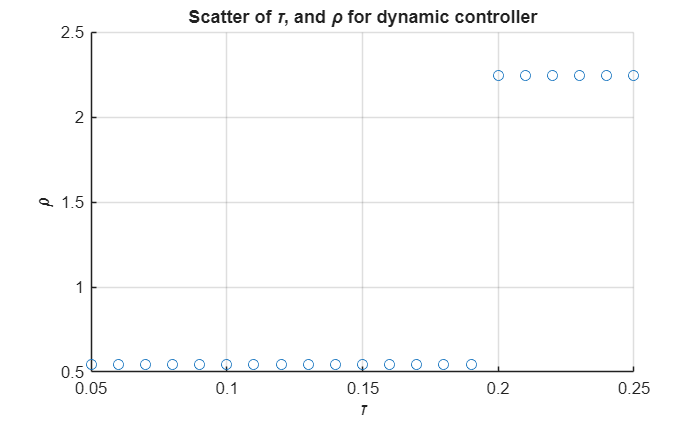



scatter(tau_values,sr_values);
xlabel('\tau');
ylabel('\rho');

title('Scatter of \tau, and \rho for dynamic controller');
grid on;


hold off